## PLOTTER

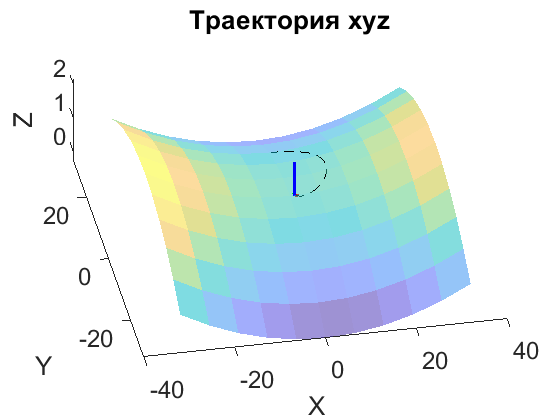

fs = 18;

%% xyz
figure 
hold on
title('Траектория xyz')
m = max(max(abs(act_states(1,:))), max(abs(act_states(2,:))))*1.5 + 3;
d = 2*m/10;
[X,Y] = meshgrid(-m:d:m);  
xlabel('X')
ylabel('Y')
zlabel('Z')
Z = surf_fcn(X,Y);
surf(X,Y,Z, 'FaceAlpha',0.5, 'EdgeColor', 'None')
plot_frame(initial_r, initial_q)
plot3(act_states(1,:),act_states(2,:),act_states(3,:), 'k--');
set(gca,'FontSize',fs)
view(-60,60)

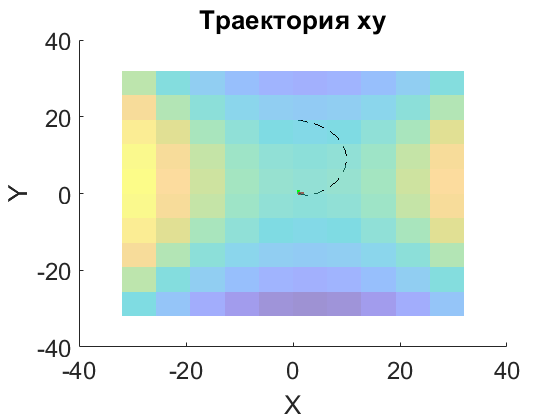


figure
hold on
title('Траектория xy')
m = max(max(abs(act_states(1,:))), max(abs(act_states(2,:))))*1.5 + 3 ;
d = 2*m/10;
[X,Y] = meshgrid(-m:d:m);  
xlabel('X')
ylabel('Y')
zlabel('Z')
Z = surf_fcn(X,Y);
surf(X,Y,Z, 'FaceAlpha',0.5, 'EdgeColor', 'None')
plot_frame(initial_r, initial_q)
plot3(act_states(1,:),act_states(2,:),act_states(3,:), 'k--');
set(gca,'FontSize',fs)
view(0, 90)

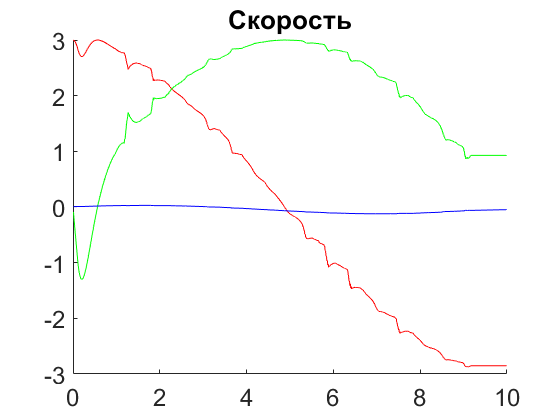

%% v
figure
hold on
title('Скорость')
plot(timeline, act_states(4, :), 'r')
plot(timeline, act_states(5, :), 'g')
plot(timeline, act_states(6, :), 'b')
set(gca,'FontSize',fs)

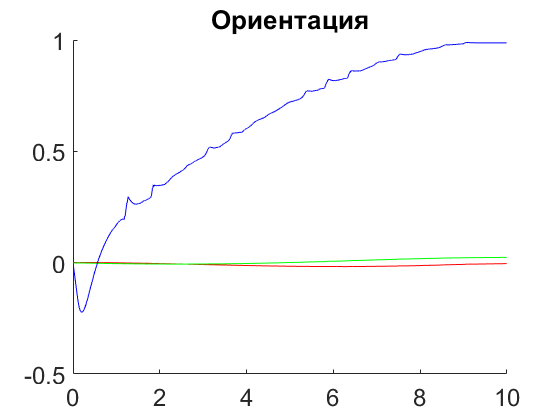


%% q
figure
hold on
title('Ориентация')
plot(timeline, act_states(11, :), 'r')
plot(timeline, act_states(12, :), 'g')
plot(timeline, act_states(13, :), 'b')
set(gca,'FontSize',fs)

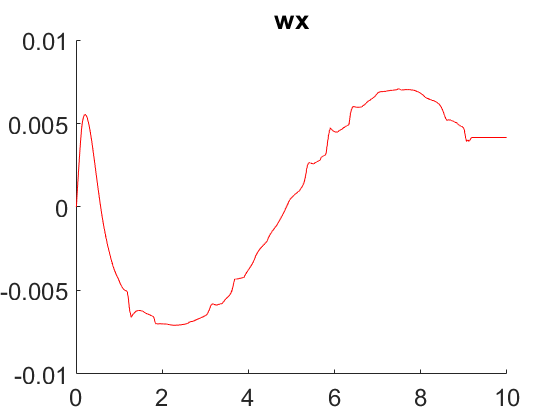


%% w
figure
hold on
title('wx')
plot(timeline, act_states(14, :), 'r')
set(gca,'FontSize',fs)

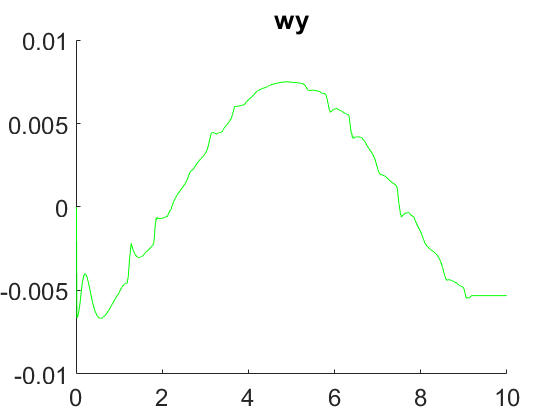


figure
hold on
title('wy')
plot(timeline, act_states(15, :), 'g')
set(gca,'FontSize',fs)

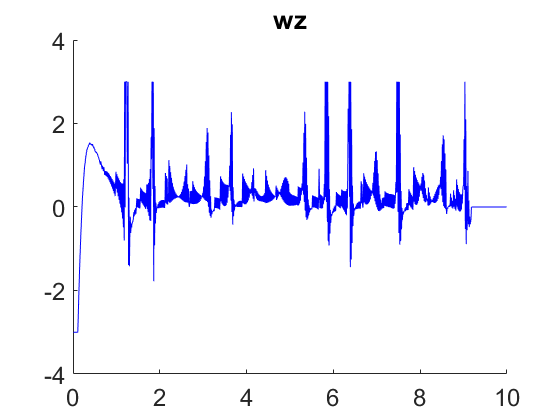


figure
hold on
title('wz')
plot(timeline, act_states(16, :), 'b')
set(gca,'FontSize',fs)

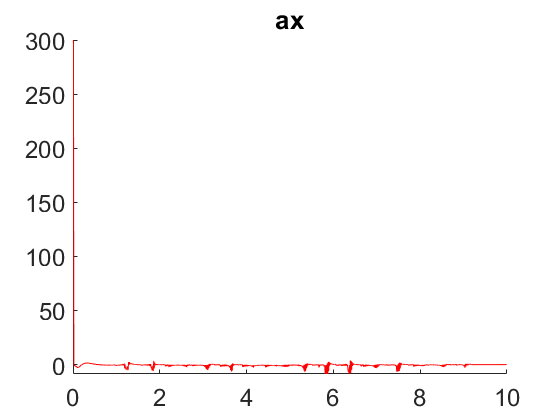


%% a
figure
hold on
title('ax')
plot(timeline, act_states(7, :), 'r')
set(gca,'FontSize',fs)

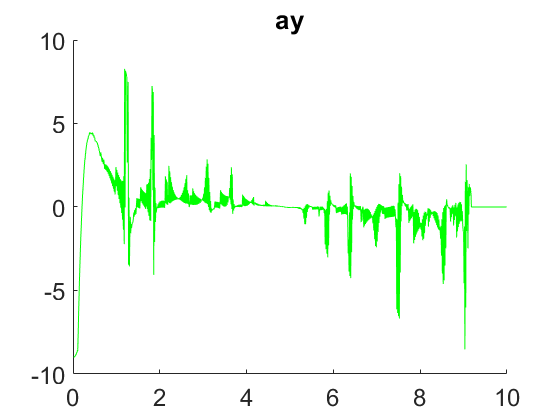


figure
hold on
title('ay')
plot(timeline, act_states(8, :), 'g')
set(gca,'FontSize',fs)

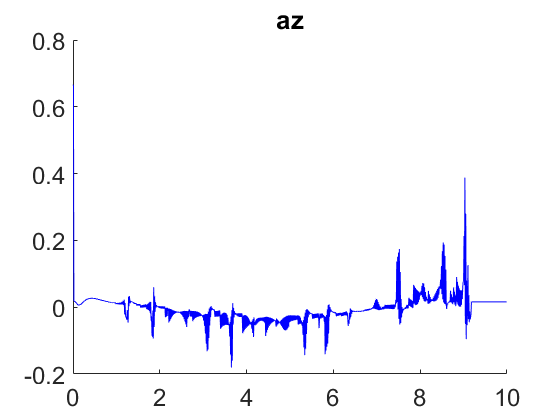


figure
hold on
title('az')
plot(timeline, act_states(9, :), 'b')
set(gca,'FontSize',fs)


% %% w_dot
% figure
% hold on
% title('wx dot')
% plot(timeline, wx_dot_act, 'r')
% set(gca,'FontSize',fs)
% 
% figure
% hold on
% title('wy dot')
% plot(timeline, wy_dot_act, 'g')
% set(gca,'FontSize',fs)
% 
% figure
% hold on
% title('wz dot')
% plot(timeline, wz_dot_act, 'b')
% set(gca,'FontSize',fs)


